1) Сохранить данные из файлов в переменные **spectra**, **NameStar**, **lambdaStart **и **lambdaDelta**.

spectra = importdata("spectra.csv");
lambdaStart = importdata("lambda_start.csv");
lambdaDelta = importdata("lambda_delta.csv");
NameStar = importdata('star_names.csv');

2) Получаем колличемво звёзд(**nStar**) и измерений(**nObs**).

nObs = size(spectra, 1);
nStar = size(spectra, 2);

3) Получаем векторы длин волн **lambda.**

lambdaEnd = lambdaStart + lambdaDelta*(nObs - 1);
lambda = (lambdaStart:lambdaDelta:lambdaEnd)';

4) Находим вектор из минимумов интенсивностей(**sHa**) спектров и их индесы(**idx**). А затем и их длины волн(**lambdaHa**) для всех звёзд.

[sHa, idx] = min(spectra);
lambdaHa = lambda(idx);

5) Высчитываем векторы скорости движения звёзд и записываем их в вектор(**speed**).

По формуле: $\vartheta =с\left(\frac{\lambda }{\lambda \iota }-1\right)$, где *с - скорость света.*$\lambda \iota$-*истинная длина*.

speed = 299792.458 * (lambdaHa/656.28 - 1);

6-7) График зависимости интенсивности излучения звёзд от их длин волн. Добавление легенды, сетки и подписи. 

grid on
hold on

xlabel('Длина волны, нм')
ylabel(['Интенсивность, эрг/см^2/c/', char(197)])
title('Спекторы звезд в созвездии Льва')
x = linspace(0.1,0.9,nStar);
for i = 1 : nStar
    if speed(i) > 0 
        fgr1 = plot(lambda, spectra(:,i), Color=[1-x(i),x(i),x(i)], LineWidth = 3);
    else
        fgr1 = plot(lambda, spectra(:,i), Color=[1-x(i),x(i),x(i)], LineWidth = 1, LineStyle="--");
    end
end
legend(NameStar)
set(gcf, 'Visible', 'on');

8) В переменую **movaway** записываем звёзды, которые удаляются от земли. 

movaway = NameStar(speed>0);
disp("Звёзды, удаляющиеся от земли:")

Звёзды, удаляющиеся от земли:


disp(movaway')

    {'HD5211'}    {'HD56030'}    {'HD94028'}



9) Сохраняем картинку в PNG.

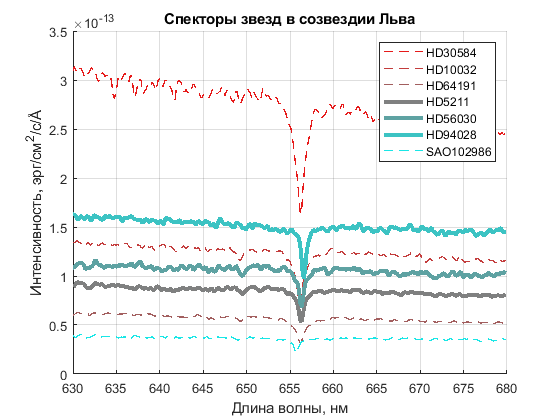

saveas(fgr1,'STARS.png')

10) Усё)))